close all;
clear all;
%%
nb_bits = 2000;
bits = randi([0,1],1,nb_bits);
Fe = 24000; % = Fs
Rb = 6000;
Tb = 1/Rb; % = Ts

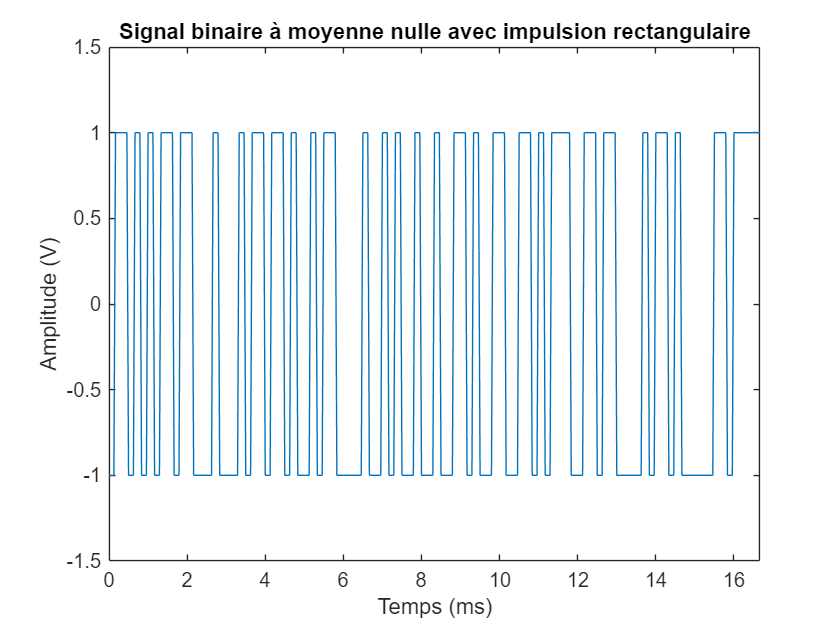

%Modulateur 1
Symboles1 = 2 * bits -1;
Ns1 = Fe/Rb; % 24000 / 6000 = 4 et pas 10 fils de con!
h = ones(1, Ns1);
Suite_diracs1 = kron(Symboles1, [1 zeros(1,Ns1-1)]); % instant ou les bits sont détecter
SignalModule1 = filter(h,1,Suite_diracs1); % création du signal rectangulaire en fonction des bits
t = (0:length(SignalModule1)-1)/Fe;
figure('Name', 'Signal 1');
plot(t*1000, SignalModule1); %t*1000 pour affichage en ms
axis([0 100*Tb*1000 -1.5 1.5]);
title("Signal binaire à moyenne nulle avec impulsion rectangulaire");
xlabel("Temps (ms)")
ylabel("Amplitude (V)")

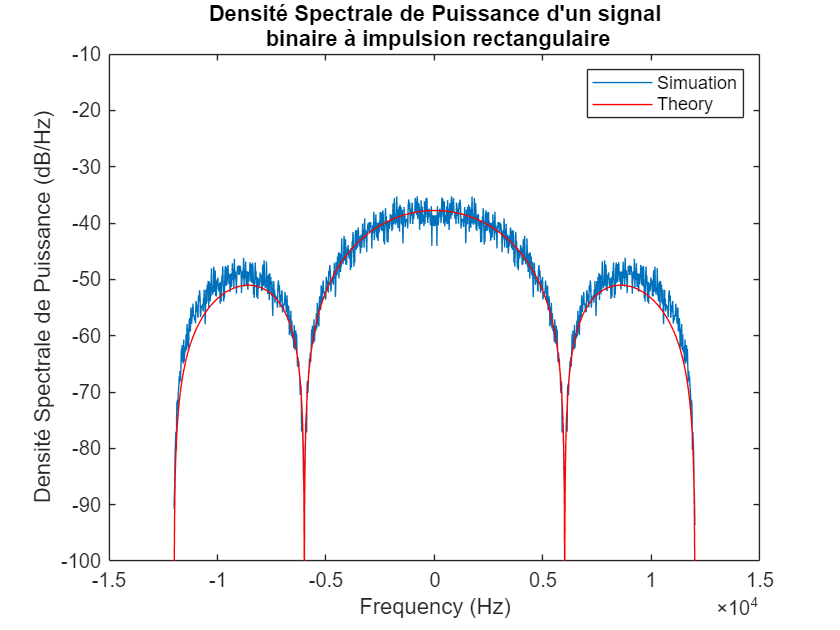

%Part of calulating and printing DSP1
figure;
DSP1_simulaire = pwelch(SignalModule1,[],[],[],Fe,'twosided', 'centered');
DSP1_simulaire_db = 10*log10(DSP1_simulaire);
axis_freq = linspace(-Fe/2,Fe/2,length(DSP1_simulaire));
%semilogy(axis_freq,DSP1_simulaire);
plot(axis_freq, DSP1_simulaire_db)
hold on;
T = Tb;
V = 1;
simga_squared = V.^2;
DSP1_theorique = 1/Rb*simga_squared*sinc(axis_freq*1/Rb).^2; % 1/Rb car on a T^2 qui sort du sinc donc T^2/T = T = 1/Rb
DSP1_theorique_db = 10*log10(DSP1_theorique);
%semilogy(axis_freq,DSP1_theorique,'r');
plot(axis_freq, DSP1_theorique_db, 'r')
legend('Simuation','Theory')
title({"Densité Spectrale de Puissance d'un signal", ...
    " binaire à impulsion rectangulaire"});
ylim([-100,-10]);
xlabel("Frequency (Hz)");
ylabel("Densité Spectrale de Puissance (dB/Hz)");

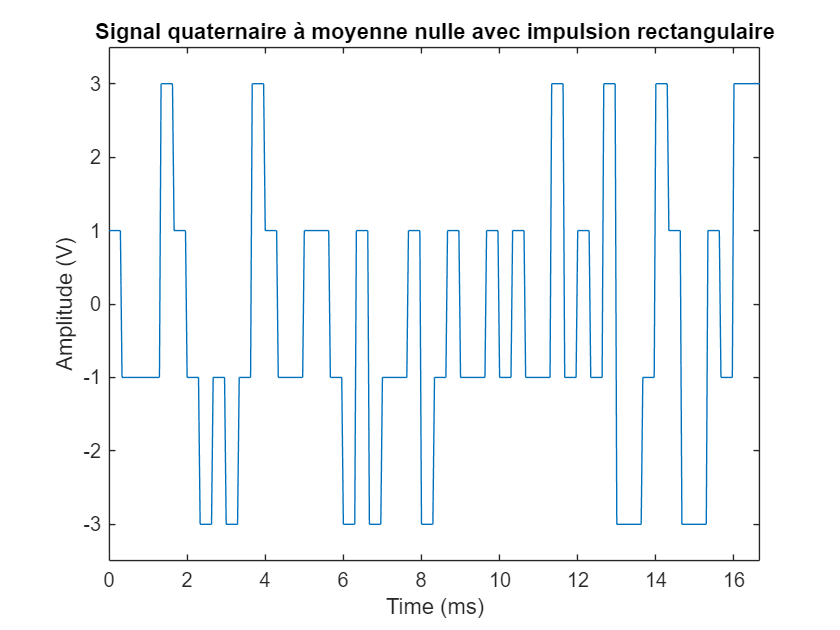


%Moulateur 2
bits_reshape = reshape(bits, 2, [])'; % deux bits par symbole maybe transpose
Symboles2 = (2 * bi2de(bits_reshape) -3).';
Ns2 = 2*Fe/Rb; %il faut 8 oscillation pour faire 2 bit = 1 symbol
Suite_diracs2 = kron(Symboles2, [1 zeros(1,Ns2-1)]);
h2 = ones(1, Ns2);
SignalModule2 = filter(h2,1,Suite_diracs2);
t2 = (0:length(SignalModule2)-1)/Fe;
figure('Name', 'Signal 2');
plot(t2*1000, SignalModule2);
axis([0 100*Tb*1000 -3.5 3.5]);
title("Signal quaternaire à moyenne nulle avec impulsion rectangulaire");
xlabel("Time (ms)")
ylabel("Amplitude (V)")

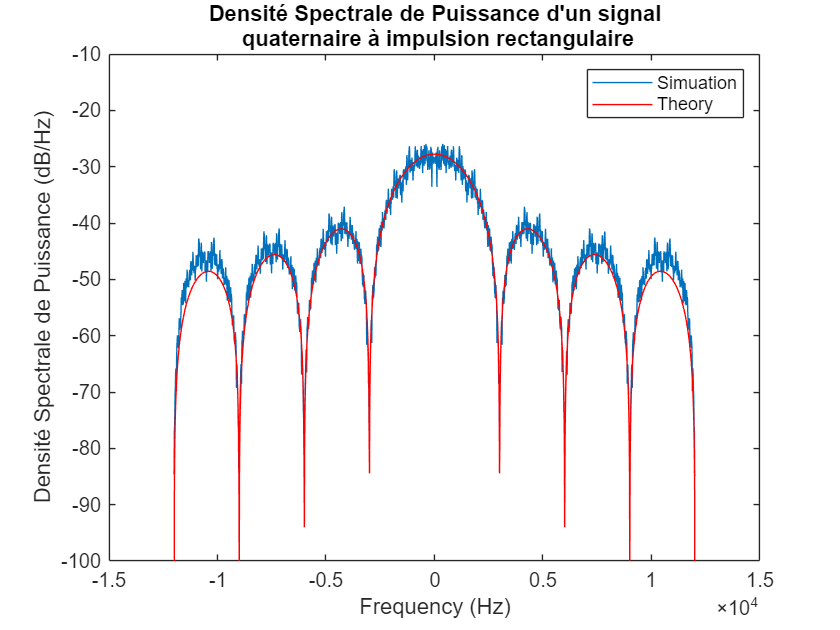


%Part of calulating and printing DSP2_Theorique
figure;
DSP2_simulaire = pwelch(SignalModule2,[],[],[],Fe,'twosided', 'centered');
DSP2_simulaire_db = 10*log10(DSP2_simulaire);
axis_freq2 = linspace(-Fe/2,Fe/2,length(DSP2_simulaire));
%semilogy(axis_freq2,DSP2_simulaire);
plot(axis_freq2, DSP2_simulaire_db)
hold on;
Tb2 = 2/(Rb); % = Ts
T2 = Tb2;
V2 = 3;
simga_squared2_calc_var = 5; %calcul de la variance de symbole2
DSP2_theorique = T2*simga_squared2_calc_var*sinc(axis_freq*T2).^2;
DSP2_theorique_db = 10*log10(DSP2_theorique);
%semilogy(axis_freq2,DSP2_theorique,'r');
plot(axis_freq2, DSP2_theorique_db, "r")
legend('Simuation','Theory')
title({"Densité Spectrale de Puissance d'un signal", ...
    " quaternaire à impulsion rectangulaire"});
ylim([-100,-10]);
xlabel("Frequency (Hz)");
ylabel("Densité Spectrale de Puissance (dB/Hz)");

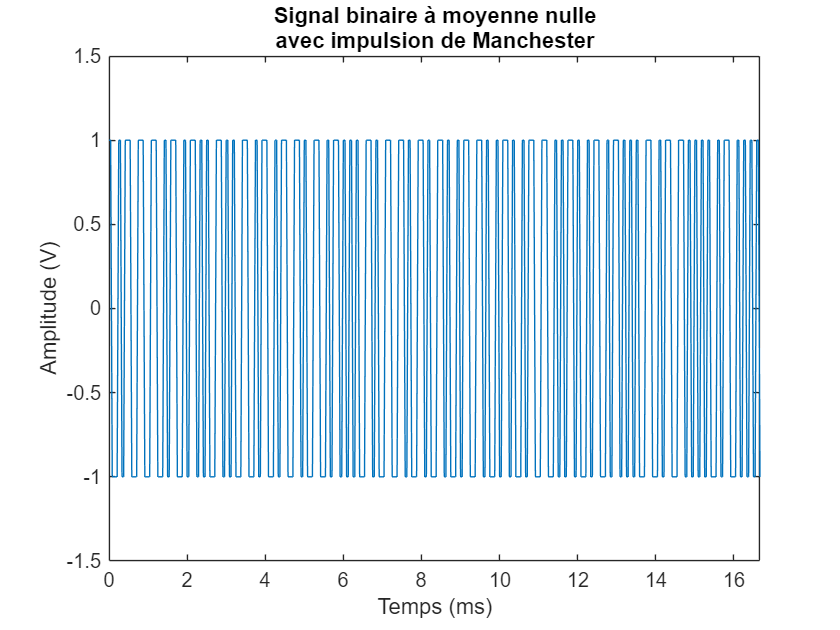

%Moulateur 3
Symboles3 = 2 * bits -1;
Ns3 = Fe/Rb;
Suite_diracs3 = kron(Symboles3, [1 zeros(1,Ns3-1)]);
h3 = [-ones(1, floor(Ns3/2)) ones(1, ceil(Ns3/2))];
SignalModule3 = filter(h3,1,Suite_diracs3);
t3 = (0:length(SignalModule3)-1)/Fe;
figure('Name', 'Signal 3');
plot(t3*1000, SignalModule3);
axis([0 100*Tb*1000 -1.5 1.5]);
title({"Signal binaire à moyenne nulle", "avec impulsion de Manchester"});
xlabel("Temps (ms)")
ylabel("Amplitude (V)")

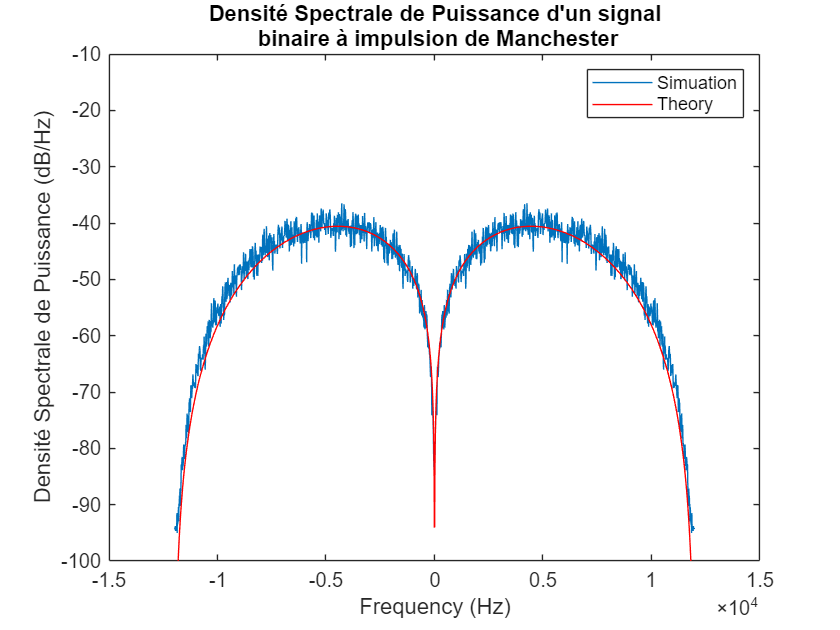


%Part of calulating and printing DSP3
figure;
DSP3_simulaire = pwelch(SignalModule3,[],[],[],Fe,'twosided', 'centered');
DSP3_simulaire_db = 10*log10(DSP3_simulaire);
axis_freq3 = linspace(-Fe/2,Fe/2,length(DSP3_simulaire));
%semilogy(axis_freq3,DSP3_simulaire);
plot(axis_freq3, DSP3_simulaire_db)
hold on;
Tb3 = 1/Rb; % = Ts
T3 = Tb3;
V3 = 1;
sigma_squared3 = V3.^2;
DSP3_theorique = T3*sigma_squared3*sinc(axis_freq3*T3/2).^2.*sin(pi*axis_freq3*T3/2).^2;
DSP3_theorique_db = 10*log10(DSP3_theorique);
%semilogy(axis_freq3,DSP3_theorique,'r');
plot(axis_freq3, DSP3_theorique_db, "r")
legend('Simuation','Theory')
title({"Densité Spectrale de Puissance d'un signal", ...
    " binaire à impulsion de Manchester"});
ylim([-100,-10]);
xlabel("Frequency (Hz)");
ylabel("Densité Spectrale de Puissance (dB/Hz)");

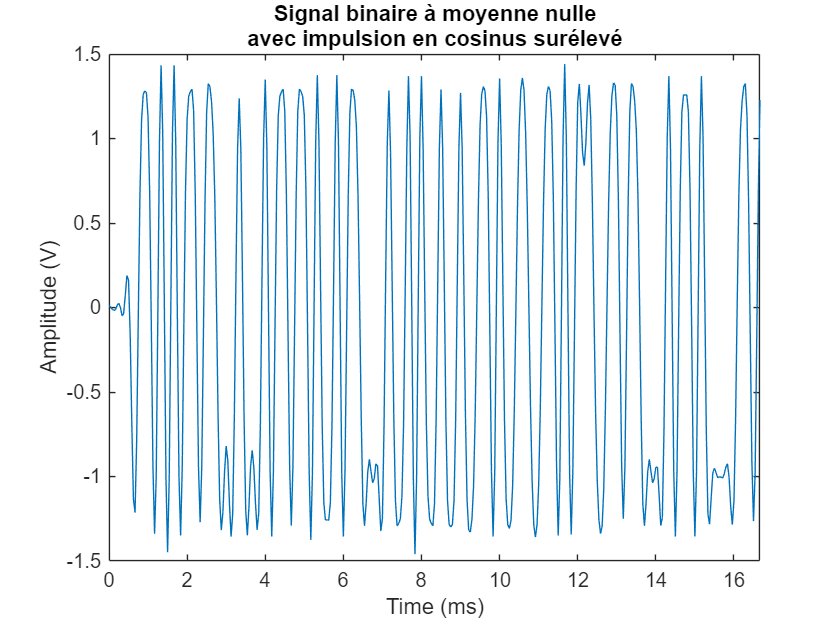

%Moulateur 4
alpha = 0.5;
Symboles4 = 2 * bits -1;
Ns4 = Fe/Rb;
Suite_diracs4 = kron(Symboles4, [1 zeros(1,Ns4-1)]);
h4 = 2*rcosdesign(alpha,8,Ns4,'sqrt');
SignalModule4 = filter(h4,1,Suite_diracs4);
t4 = (0:length(SignalModule4)-1)/Fe;
figure('Name', 'Signal 4');
plot(t4*1000, SignalModule4);
axis([0 100*Tb*1000 -1.5 1.5]);
title({"Signal binaire à moyenne nulle", "avec impulsion en cosinus surélevé"});
xlabel("Time (ms)")
ylabel("Amplitude (V)")

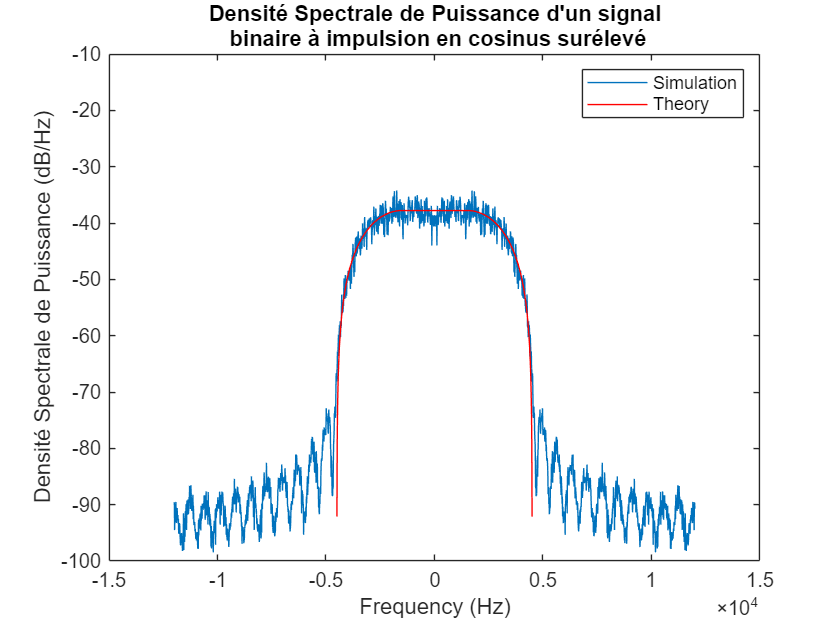

%Part of calulatting and printing DSP4_Simulaire
figure;
DSP4_simulaire = pwelch(SignalModule4,[],[],[],Fe,'twosided', 'centered');
DSP4_simulaire_db = 10*log10(DSP4_simulaire);
axis_freq4 = linspace(-Fe/2,Fe/2,length(DSP4_simulaire));
%semilogy(axis_freq4,DSP4_simulaire);
plot(axis_freq4, DSP4_simulaire_db)
hold on;
Tb4 = 1/Rb;
Tb4;
V4 = 1;
sigma_squared4 = V4.^2;
DSP4_theorique = sigma_squared4 * Tb4* ones(size(axis_freq4));
mask1 = abs(axis_freq4)>((1-alpha)/(2*Tb4));
DSP4_theorique(mask1) = sigma_squared4*Tb4/2*(1 + cos(pi*Tb4/alpha* (abs(axis_freq4(mask1)) - (1 - alpha)/(2*Tb4))));
mask2 = abs(axis_freq4)>((1+alpha)/(2*Tb4));
DSP4_theorique(mask2) = 0;
DSP4_theorique_db = 10*log10(DSP4_theorique);
%semilogy(axis_freq4,DSP4_theorique,'r');
plot(axis_freq4, DSP4_theorique_db, "r")
legend('Simulation','Theory')
title({"Densité Spectrale de Puissance d'un signal", ...
    " binaire à impulsion en cosinus surélevé"});
ylim([-100,-10]);
xlabel("Frequency (Hz)");
ylabel("Densité Spectrale de Puissance (dB/Hz)");

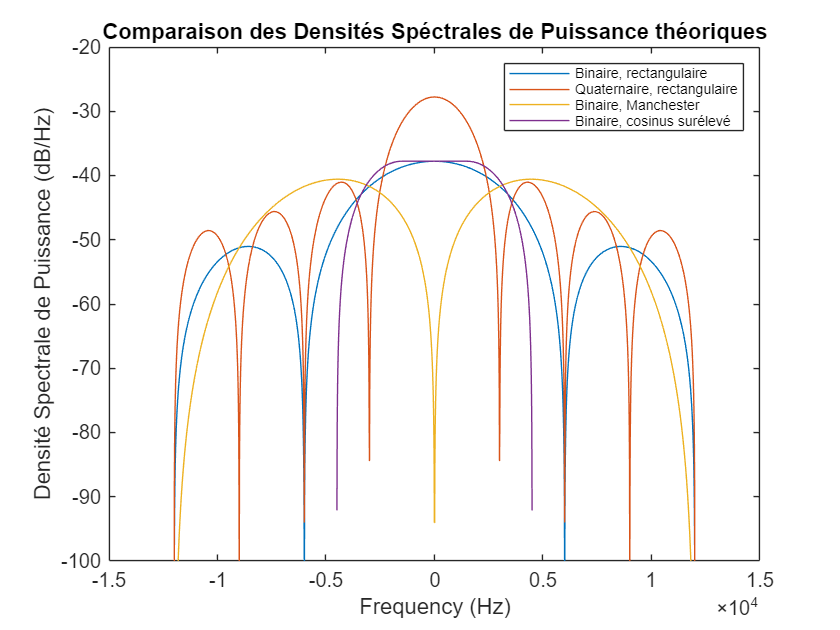


%2
figure('Name', 'DSP-Simulaire');
%semilogy(axis_freq,DSP1_theorique);
plot(axis_freq, DSP1_theorique_db)
hold on;
%semilogy(axis_freq,DSP2_theorique);
plot(axis_freq, DSP2_theorique_db)
hold on;
%semilogy(axis_freq,DSP3_theorique);
plot(axis_freq, DSP3_theorique_db)
hold on;
%semilogy(axis_freq,DSP4_theorique);
plot(axis_freq, DSP4_theorique_db)
title('Comparaison des Densités Spéctrales de Puissance théoriques')
legend('Binaire, rectangulaire', 'Quaternaire, rectangulaire', ...
    'Binaire, Manchester', 'Binaire, cosinus surélevé', "Fontsize", 7);
ylim([-100,-20]);
xlabel("Frequency (Hz)");
ylabel("Densité Spectrale de Puissance (dB/Hz)");